Testing making a sine.

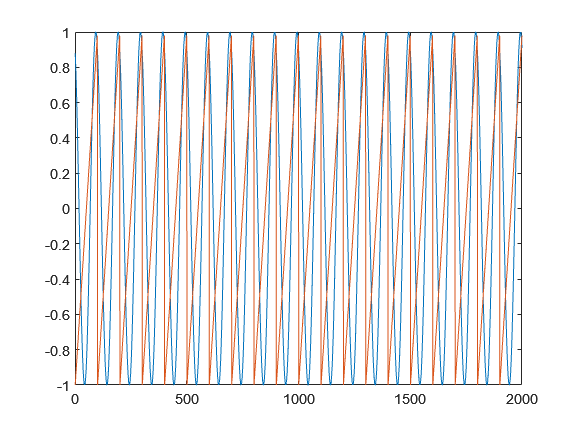

fs = 10e3; % sample frequency (F_s)
spf = 2e3; % samples per frame

sine1 = dsp.SineWave(1, 1e2, -10.5, 'SampleRate', fs, 'SamplesPerFrame', spf);

signal2 = audioOscillator ('sawtooth', 1e2, 'SampleRate', fs, 'SamplesPerFrame', spf);
noise = dsp.ColoredNoise('white','SamplesPerFrame',spf);
x2 = signal2();
plot(sine1())
hold on
plot(x2)
hold off

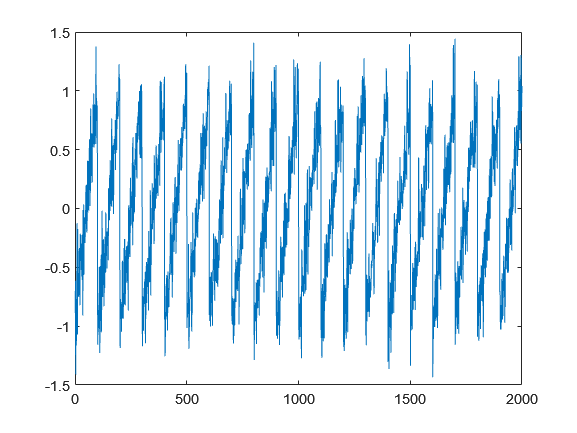

%plot(noise())
%axis([0 0.2 -1 1])

% noise = 0.2*rand(sine1.SamplesPerFrame, 1);

noisy_x = x2+ 0.2*noise();

plot(noisy_x)

%axis([0 0.2 -1 1])

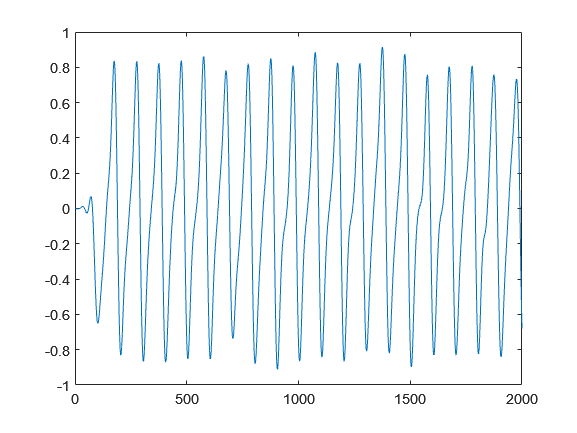

Fs = sine1.SampleRate;
filtertype = 'FIR';
Fpass = 2e2;
Fstop = 4e2; 
Rp = 0.1;
Astop = 80;
FIRLPF = dsp.LowpassFilter('SampleRate',Fs, ...
                             'FilterType',filtertype, ...
                             'PassbandFrequency',Fpass, ...
                             'StopbandFrequency',Fstop, ...
                             'PassbandRipple',Rp, ...
                             'StopbandAttenuation',Astop);

filtered_x = FIRLPF(noisy_x);

plot(filtered_x)

%axis([0 0.2 -1 1])

Compare the peak-to-peak of the original and filtered signals. 

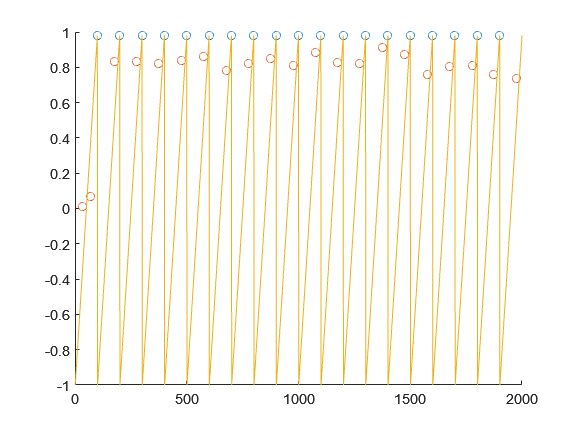

[pks_true, loc_true] = findpeaks(x2);
[pks_noisy, loc_noisy] = findpeaks(noisy_x);
[pks_filtered, loc_filtered] = findpeaks(filtered_x);

scatter(loc_true, pks_true)
hold on
%scatter(loc_noisy, pks_noisy)
scatter(loc_filtered, pks_filtered)
plot(x2)
hold off

What happens if we just sum another noisy sine?

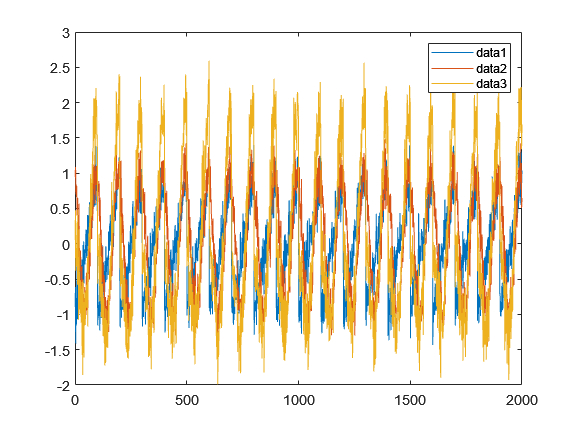

sine_wave = sine1();
sine_noise = 0.2 .* noise();
noisy_sine = sine_wave + sine_noise;

% signal summation
signal_combo = noisy_x + noisy_sine;
plot(noisy_x)
hold on
plot(noisy_sine)
plot(signal_combo)
legend
hold off

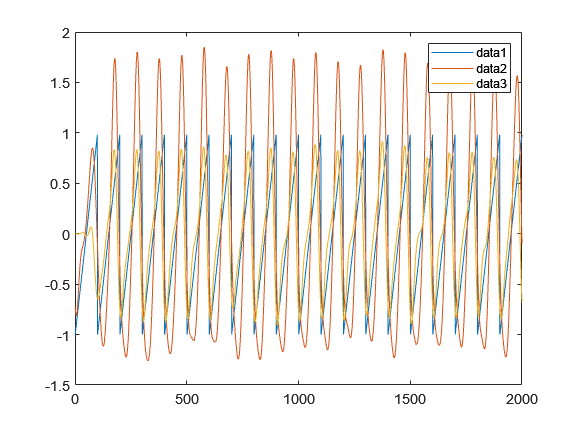

filtered_combo = FIRLPF(signal_combo);
[pks_combo, loc_combo] = findpeaks(filtered_combo);

plot(x2)
hold on
plot(filtered_combo)
plot(filtered_x)
legend 
hold off

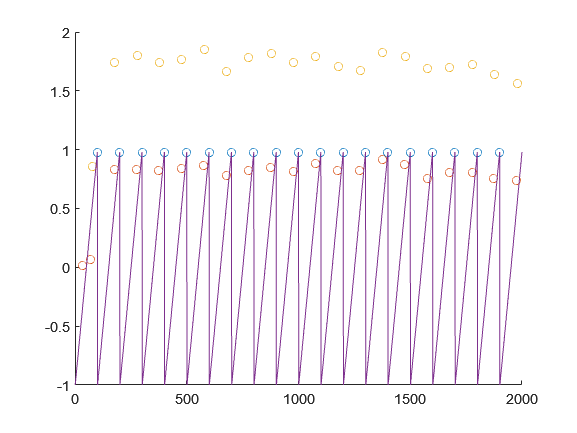



scatter(loc_true, pks_true)
hold on
%scatter(loc_noisy, pks_noisy)
scatter(loc_filtered, pks_filtered)
scatter(loc_combo, pks_combo)
plot(x2)
hold off

Generate some histograms to help show results

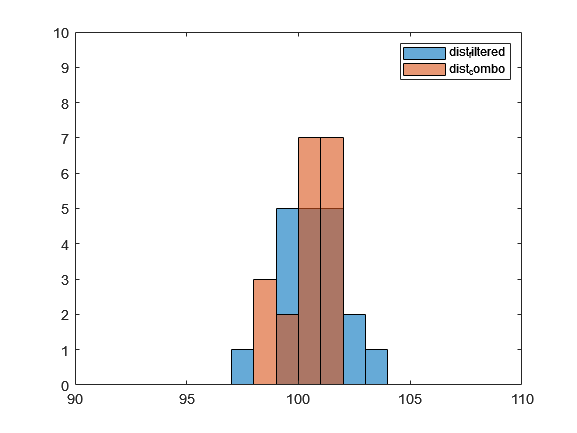


dist_true = diff(loc_true);
dist_filtered = diff(loc_filtered);
dist_combo = diff(loc_combo);

%histogram(dist_true, 1:max(dist_true))

histogram(dist_filtered, 1:max(dist_filtered))
hold on

histogram(dist_combo, 1:max(dist_combo))
axis([90 110 0 10])
legend
hold off

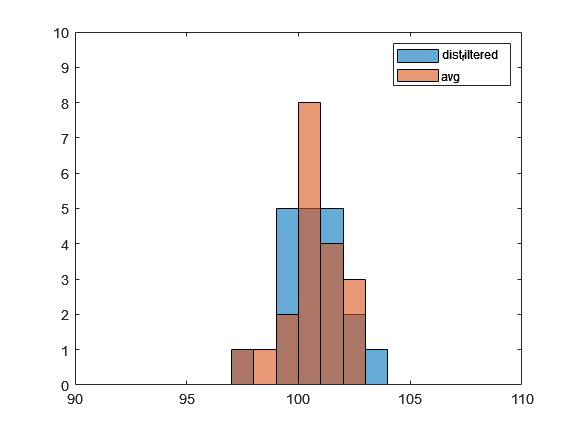

filtered_sine = FIRLPF(noisy_sine);
[pks_sin, loc_sin] = findpeaks(filtered_sine);
dist_sine = diff(loc_sin);

avg = round(0.7 .* dist_filtered(2:20) + 0.3 .* dist_sine);

histogram(dist_filtered, 1:max(dist_filtered))
hold on

histogram(avg, 1:max(avg))
axis([90 110 0 10])
legend
hold off

Averaging on the peak to peak removes the need to correlate the timeseries of the signals! which is neat!!

Notes for 11/10/21 Meeting

General Questions

- What data are we fusing? We can do raw signals, we could do low-passed signals, we could use some simple weighted sum approach to combine individual HR estimates. Maybe we try all three of these? My gut is that the middle option is kind of redundant to the first option, since the fused filter should be able to do low pass filtering itself, but maybe we simplify the design by pre-determining the filter. 

- Do our microphones need calibration, to subtract out environmental noise? Is it muffled enough by being close to the skin?

- Extended or Unscented Kalman filter, if we go that route. Plain will not handle the non-linearities well, Extended may not handle the discontuous nature of the PPG signal very well. Could require complex analysis/math formulation, but not something that's not possible. 

- In the case of fusing raw/low-passed data, let's call that output something. 

[COMPRESSED SENSING OF AUDIO SIGNALS USING MULTIPLE SENSORS](https://d1wqtxts1xzle7.cloudfront.net/33032572/1569104572.pdf?1392809702=&response-content-disposition=inline%3B+filename%3DCOMPRESSED_SENSING_OF_AUDIO_SIGNALS_USIN.pdf&Expires=1636560990&Signature=W2XkijpepPDdP4qHI-LUT~WlD7S9v9bqBuJn4mfcNASCmIJ39HHEc1KfOnBQkSxIGpgzDSdYzuBhzoCxXFN8u-4ePHuCtd6LyL8up5EVuH4N0ECXXJ959lwGZ9g-ndTRjTtOc4qk001hpTKAQ5-0dIx3IqKDh7UI3Ur6P8mn50R0xg2DO~7Jp9MMp5UU5MzoFuJ3sGn-NyqAXDkldbfnSz6Rw2xyoMpt9XwP2cJDtucJSWT2yjhS-xryDdA0k7nNuCPtX7yWIegRuC2JDJaqVU2z1RkTVXLjczBtLdYgC503Zd38vFxBuCx285TLKW~J-Pqy13FloyrP5KkJXESaGw__&Key-Pair-Id=APKAJLOHF5GGSLRBV4ZA)

- Compreses audio sensing data in a sensor network (not super relevant to  us at this point)

- Seems to use a very simple method of combining the signals by taking the mean of the recovered (from compression) signals.

[CASSANDRA: audio-video sensor fusion for aggression detection](https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.409.3137&rep=rep1&type=pdf)

- Basically, a smart security camera that combines aggression estimates from visual estimation with aggression estimates from sound to give an overall estimate of the scene's aggression. In a train station, so also monitors for the presence of trains to subtract their effect from the scnee.

- Implemented with Bayesian networks. Bayesian networks are very common in audio processing, especially for speech recognition tasks. In some ways, detecting the peak is kind of like a classification of the signal, so not a totally dissimilar application.

- They seem to fuse the results of their aggression analysis, don't utilize it as a method for filtering each signal. 

[Robust Sensor Fusion: Analysis and Application to Audio Visual Speech Recognition](https://link.springer.com/content/pdf/10.1023/A:1007468413059.pdf)

- Supports the idea of a bayesian approach to analyzing audio data

Unclear: what are the runtime rquirements of bayesian network and how implementablel will it be on mCU